% MECH 6318 - HW 2
% Jonas Wagner
% 2021-09-07

clear
close all

% Problem 5.3 -----------------------------------------
H = [ 2, -3;
     -3, 20]

H =      2    -3
    -3    20


f = zeros(2,1);

A = [-2, -1;
     -1, -1]

A =     -2    -1
    -1    -1


b = [-4;
      5]

b =     -4
     5



lb = -5

lb = -5

ub = 5

ub = 5


x0 = ones(2,1)

x0 =      1
     1



% Part a
[x_opt,f_min] = quadprog(H,f,A,b,[],[],lb,ub)

x_opt =     1.8298
    0.3404


f_min = 2.6383


% Part b
[x_opt_b,f_min_b] = quadprog(H,f,A(1,:),b(1,:),[],[],lb,ub)

x_opt_b =     1.8298
    0.3404


f_min_b = 2.6383


% Part c
[x_opt_c,f_min_c] = quadprog(H,f,[],[],[],[],lb,ub)

x_opt_c =      0
     0


f_min_c = 0

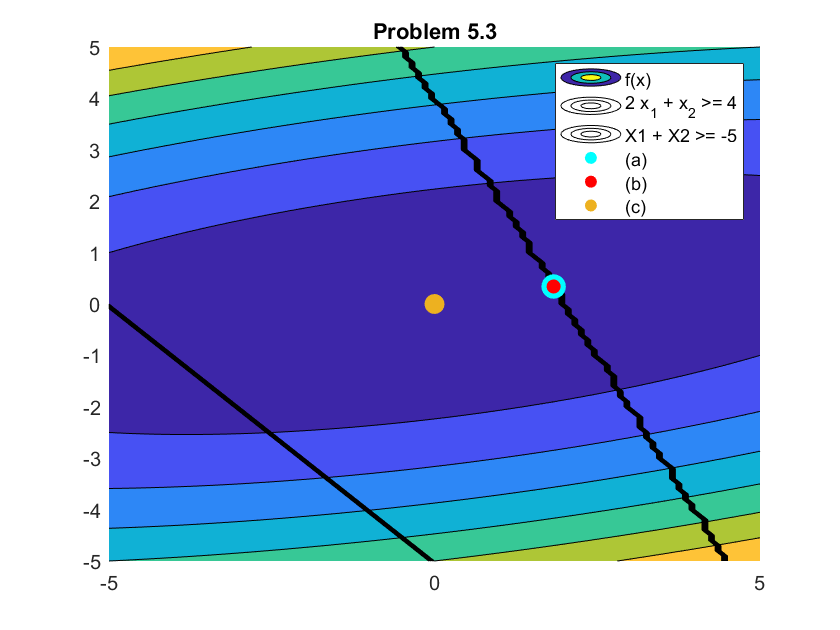


% Part d
[X1,X2] = meshgrid(lb:0.1:ub,lb:0.1:ub);
F = X1.^2 + 10.*X2.^2 - 3.*X1.*X2;

figure()
hold on
contourf(X1, X2, F, 'DisplayName', 'f(x)')
contour(X1, X2, 2 * X1 + X2 >=  4, 'k',...
    'DisplayName', '2 x_1 + x_2 >= 4')
contour(X1, X2,     X1 + X2 >= -5, 'k',...
    'DisplayName', 'X1 + X2 >= -5')
scatter(x_opt(1) ,x_opt(2), 150, 'filled', 'c',...
    'DisplayName', '(a)')
scatter(x_opt_b(1) ,x_opt_b(2), 50, 'filled', 'r',...
    'DisplayName', '(b)')
scatter(x_opt_c(1) ,x_opt_c(2), 100, 'filled', 'o',...
    'DisplayName', '(c)')
legend
title('Problem 5.3')


% Problem 5.4 --------------------------------------------
f = [20; 64]

f =     20
    64



A = [-25, -70]

A =    -25   -70


b = -2100

b = -2100


lb = [ 0;  0]

lb =      0
     0


ub = [70; 50]

ub =     70
    50



% Part a
[x_opt, f_opt] = linprog(f, A, b, [], [], lb, ub)

x_opt =     70
     5


f_opt = 1720


% Part b
[x_opt_b, f_obt_b] = fmincon(...
    @(x) 20 * x(1) + 64 * x(2),...
    [0; 0], A, b, [], [], lb, ub)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x_opt_b =    70.0000
    5.0000


f_obt_b = 1.7200e+03